%--- Oval Perimeter ---

clc,clear,close all
syms t f(t)

disp('--- Oval Perimeter ---')

--- Oval Perimeter ---



%a and b are the radiuses (taken from user)
disp('radiuses:')

radiuses:


a=input("please input the first radiuse (a):")

a = 5

b=input("please input the second radiuse (b):")

b = 4

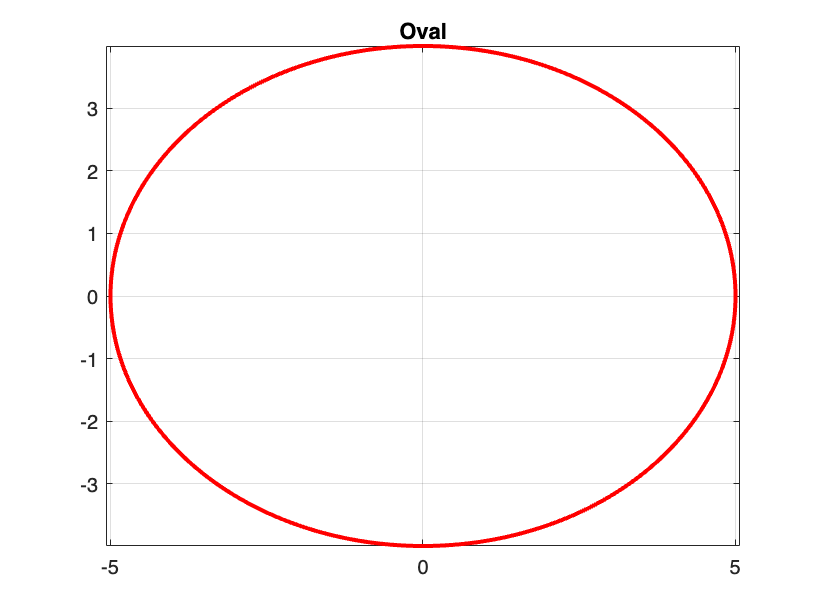


ovalDrawer(a,b)


%finding perimeter integral
x= a*cos(t);
y= b*sin(t);

x= diff(x,t);
y= diff(y,t);

disp('integral Function:')

integral Function:


f(t)= sqrt(sum([x,y].*[x,y]))

$$f(t) = \sqrt{16\,{\cos\left(t\right)}^{2}+25\,{\sin\left(t\right)}^{2}}$$


%calculating numerical integral

% accuracy of integral
parts=100;

points(1,1:parts)=linspace(0,2*pi,parts);
points(2,1:parts)=f(points(1,1:parts));
h=(points(1,2)-points(1,1));

integralAns=points(2,1)+2*sum(points(2,2:(parts-1)))+points(2,parts);
integralAns=vpa((h/2)*integralAns)

$$integralAns = 28.361667888974483986430641380139$$


%ramanujan formula to find oval perimeter
c=((a-b)^2)/((a+b)^2);
ramanujanAns=vpa(pi*(a+b)*(1+((3*c)/(10+sqrt(4-3*c)))))

$$ramanujanAns = 28.361667888974295692605664953589$$

function ovalDrawer(a,b)
    t=linspace(0,2*pi,1000);
    x=a*cos(t);
    y=b*sin(t);
    plot(x,y,'color','r','LineWidth',2)
    axis equal
    grid on
    title('Oval')
end